# Defining transfer functions in MATLAB and computing poles

Assume that the transfer function is already known and we want to enter this into MATLAB; this file gives a number of examples. Similarly, at times the transfer function could have been auto-generated, and subsequently we want to know what are the coefficients or where are the poles and zeros. We illustrate the ***tfdata.m*** and ***pzmap.m*** files for computing these. 

You will need the control toolbox for this file.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Example of a transfer function  (modify the code in line 1 for different examples)

- Example of a transfer function

- Example of a transfer function with zero coefficients

- Extracting numerator and denominator coefficients from a transfer function model

- Computing poles and zeros from the transfer function

## 1. Example of a transfer function  (modify the code in line 1 for different examples)

The file tf.m takes as arguments the coefficients of the numerator and denominator to create a transfer function object. This will be clear from several examples

$G\left(s\right)=\frac{1}{s^2 +5s+6};\;$has numerator with coefficient 1 and denominator with coefficients 1, 5 and 6

G=tf(1,[1 5 6])

G =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



MATLAB allocates the coefficients to powers of 's' in order, beginning from lowest power on the right.

## 2. Example of a transfer function

Look at his higher order example and see how MATLAB automatically allocates the powers of 's' corresponding to the order in which the coefficients are supplied. 

$\textrm{G2}\left(s\right)=\frac{s^2 +0\ldotp 1s+4}{{5s^3 +2s}^2 -4s+6\ldotp 3};\;$has numerator with coefficients 1, 0.1 and 4 and denominator with coefficients 5, 2, -4 and 6.3.

G2=tf([1 0.1 4],[5 2 -4 8.3])

G2 =
 
       s^2 + 0.1 s + 4
  -------------------------
  5 s^3 + 2 s^2 - 4 s + 8.3
 
Continuous-time transfer function.



## 3. Example of a transfer function with zero coefficients

What if some of the coefficients are zero? Simple, just include zeros in the coefficients that you supply.

$\textrm{G3}\left(s\right)=\frac{s^3 -0\ldotp 4s+5\ldotp 8}{{2\ldotp 1s^4 +7s}^2 +4\ldotp 2s};\;$note this has no $s^2$ in the numerator and no $s^3$ and $s^0$ in the denominator so we put zeros in those positions in the tf.m call line below.

G3=tf([1 0 -0.4 5.8],[2.1 0 7 4.2 0])

G3 =
 
     s^3 - 0.4 s + 5.8
  -----------------------
  2.1 s^4 + 7 s^2 + 4.2 s
 
Continuous-time transfer function.



## 4. Extracting numerator and denominator coefficients from a transfer function model

It may be that the transfer function has been defined elsewhere and you want to know exactly what the coefficients are. MATLAB has a simple tool for this called*** tfdata.m. ***The built in help will give more detail so we illustrate just one simple case. Note how the tow vectors are of the same length so with strictly proper transfer functions the numerator vector will have some leading zeros.

disp('BELOW ARE EXAMPLES OF HOW TO EXTRACT NUMERATOR/DENOMINATOR COEFFICIENTS')

BELOW ARE EXAMPLES OF HOW TO EXTRACT NUMERATOR/DENOMINATOR COEFFICIENTS


G=tf([1 4 2],[1 0 3 5])

G =
 
  s^2 + 4 s + 2
  -------------
  s^3 + 3 s + 5
 
Continuous-time transfer function.



[n,d]=tfdata(G,'v')

n =      0     1     4     2


d =      1     0     3     5


H =tf(3,[1 -3 -5])

H =
 
        3
  -------------
  s^2 - 3 s - 5
 
Continuous-time transfer function.



[nH,dH] = tfdata(H,'v')

nH =      0     0     3


dH =      1    -3    -5


## 5. Computing poles and zeros from the transfer function

The poles and zeros can be computed using the pzmap.m file.  Depending on how the statement is used you will either:

- Get numerical values into the workspace.

- A plot showing poles with 'X' and zeros with 'O'.

#### Compute the numerical values of poles and zeros

disp('SECTION 5 BELOW ARE POLE-ZERO COMPUTATIONS')

SECTION 5 BELOW ARE POLE-ZERO COMPUTATIONS


[Gpoles, Gzeros]=pzmap(G)

Gpoles =    0.5771 + 1.9998i
   0.5771 - 1.9998i
  -1.1542 + 0.0000i


Gzeros =    -3.4142
   -0.5858


[G2poles, G2zeros]=pzmap(G2)

G2poles =   -1.5760 + 0.0000i
   0.5880 + 0.8412i
   0.5880 - 0.8412i


G2zeros =   -0.0500 + 1.9994i
  -0.0500 - 1.9994i


[G3poles, G3zeros]=pzmap(G3)

G3poles =    0.0000 + 0.0000i
   0.2750 + 1.8869i
   0.2750 - 1.8869i
  -0.5501 + 0.0000i


G3zeros =   -1.8709 + 0.0000i
   0.9354 + 1.4917i
   0.9354 - 1.4917i


#### Plot the poles and zeros on an Argand diagram

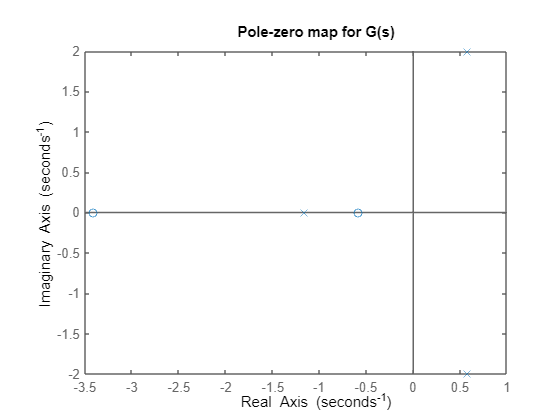

figure
pzmap(G)
title('Pole-zero map for G(s)')

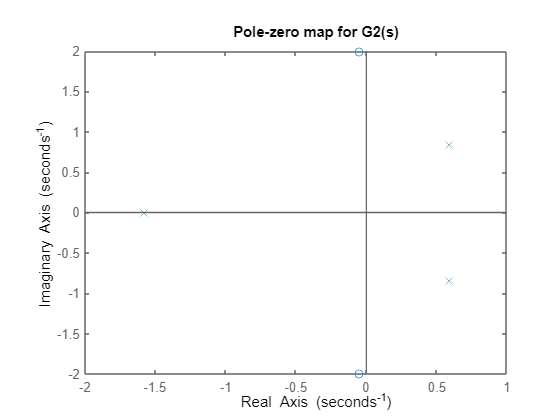

figure
pzmap(G2)
title('Pole-zero map for G2(s)')

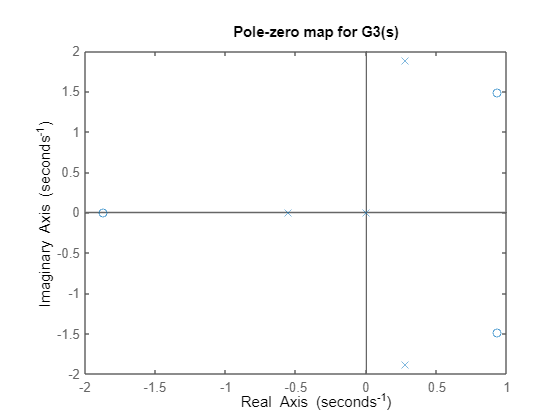

figure
pzmap(G3)
title('Pole-zero map for G3(s)')